# PSI3531 - Processamento de Sinais Aplicado

# Experiência 5

# Codificação de imagens segundo o padrão JPEG

Aluno:            André Oliveira Françani     

Núm. USP:    9017471 

Prof. Dr. Vitor H. Nascimento

## 5 - Parte Experimental

### 5.1 Sub-amostragem do sinal de crominância

Leitura da imagem *cat.png:*

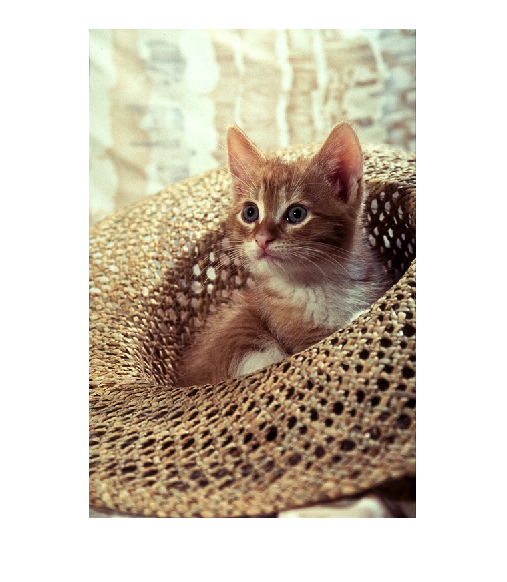

clear
clc

gato = imread('cat.png');
gato = double(gato);
[N1, N2, c] = size(gato);
figure(1); imshow(uint8(gato));

Transformação para o padrão $\textrm{YCbCr}$, em que


$$\begin{array}{l}
Y=\alpha_R R+\alpha_G G+\alpha {\;}_B B\\
C_b =\frac{1}{2\left(1-\alpha_B \right)}\left(B-Y\right)\\
C_r =\frac{1}{2\left(1-\alpha_R \right)}\left(R-Y\right)
\end{array}$$


%matrizes de pixels RGB
R = gato(:,:,1);
G = gato(:,:,2);
B = gato(:,:,3);

%transformação YCbCr
alpha_R = 0.299;
alpha_G = 0.587;
alpha_B = 0.114;

%Luminância Y
Y = alpha_R*R + alpha_G*G + alpha_B*B;

%termos de crominância: Cb e Cr
Cb = 1/(2*(1-alpha_B))*(B-Y);
Cr = 1/(2*(1-alpha_R))*(R-Y);

%Visualização do padrão YCbCr gerado
figure(2); 
subplot(1,3,1); imshow(uint8(Y) ); title('Y');
subplot(1,3,2); imshow(uint8(Cb)); title('C_b');
subplot(1,3,3); imshow(uint8(Cr)); title('C_r');

Sub-amostragem dos sinais de crominância $C_b$ e $C_{r\;}$:

%subamostragem por fator 2 nas direções vertical e horizontal
Cb_sub = Cb(1:2:end, 1:2:end);
Cr_sub = Cr(1:2:end, 1:2:end);

Recuperação dos sinais RGB usando a fórmula anterior inversa e interpolação linear usando o filtro com resposta ao impulso.


$$h=\;\left\lbrack \begin{array}{ccc}
0\ldotp 25 & 0\ldotp 5 & 0\ldotp 25\\
0\ldotp 5 & 1 & 0\ldotp 5\\
0\ldotp 25 & 0\ldotp 5 & 0\ldotp 25
\end{array}\right\rbrack$$


%interpolação linear usando o filtro
h = [0.25 0.5 0.25; 0.5 1 0.5; 0.25 0.5 0.25];

Cb_interpolado = zeros(size(Y));
Cb_interpolado(1:2:end, 1:2:end) = Cb_sub;
Cb_interpolado = filter2(h, Cb_interpolado);

Cr_interpolado = zeros(size(Y));
Cr_interpolado(1:2:end, 1:2:end) = Cr_sub;
Cr_interpolado = filter2(h, Cr_interpolado);

%conversão para RGB
R_new = 2*(1-alpha_R)*Cr_interpolado + Y;
B_new = 2*(1-alpha_B)*Cb_interpolado + Y;
G_new = (Y - alpha_R*R_new - alpha_B*B_new)/alpha_G;

%reuperação da imagem RGB
gato_recuperado = cat(3, R_new, G_new, B_new);

Comparação da imagem recuperada com a imagem original.

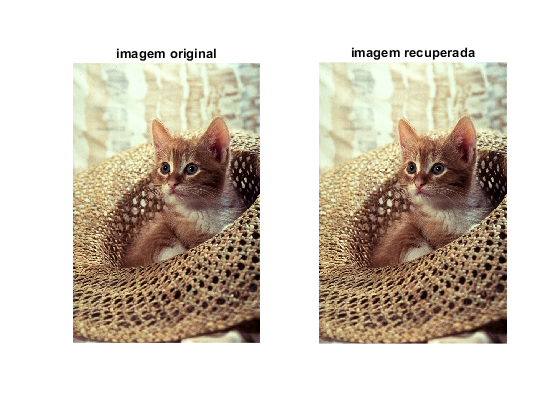

figure(3)
subplot(1,2,1); imshow(uint8(gato)); title('imagem original');
subplot(1,2,2); imshow(uint8(gato_recuperado)); title('imagem recuperada');

Cálculo da *peak signal-to-noise ratio *(PSNR):

%Cálculo da PSNR
Bits = 8; 
MSE = (abs(gato-gato_recuperado).^2)/(N1*N2);
MSE = sum(MSE, [1,2]);
MSE = mean(MSE,3);
PSNR = 10*log10((2^Bits-1)^2/MSE)

PSNR = 46.4555

### 5.2 Quantização da transformada discreta do cosseno (DCT)

Foram acrescentadas linhas e colunas aos canais $Y,C_{b\;} ,C_r$ para que as dimensões das imagens sejam múltiplas de 8. Além disso, foi feita a decimação dos sinais de crominância antes de aplicar a DCT. 

%criando a imagem espelhada com padding
padY  = 8-mod(size(Y) ,8);
padCb = 8-mod(size(Cb) ,8);
padCr = 8-mod(size(Cr) ,8);

Y_pad =  padarray(Y, padY, 'symmetric', 'post');
Cb_pad = padarray(Cb, padCb, 'symmetric', 'post');
Cr_pad = padarray(Cr, padCr, 'symmetric', 'post');

%decimação por 2
Cb_sub = Cb_pad(1:2:end, 1:2:end);
Cr_sub = Cr_pad(1:2:end, 1:2:end);

A DCT foi aplicada a blocos $8\times 8$ de cada canal, subtraindo 128 das imagens para a correção de nível DC.

%DCT aplicada a blocos 8x8 em cada canal
Ydct  = blkproc(Y_pad-128 , [8 8], @dct2);
Cbdct = blkproc(Cb_sub-128, [8 8], @dct2);
Crdct = blkproc(Cr_sub-128, [8 8], @dct2);

Em seguida foi feita a quantização dos coeficientes da DCT usando $\textrm{kQ}$ como passo de quantização, com $k=1,2,3\ldotp$

%Tabela de quantização Q
Q = [8 11 10 16 24 40 51 61;
    12 12 14 19 26 58 60 55;
    14 13 16 24 40 57 69 56;
    14 17 22 29 51 87 80 62;
    18 22 37 56 68 109 103 77;   
    24 35 55 64 81 104 113 92;
    49 64 78 87 103 121 120 101;
    72 92 95 98 112 100 103 99];

%inicializando as variáveis
Y_q  = zeros(3,size(Ydct,1), size(Ydct,2));
Cb_q = zeros(3,size(Cbdct,1), size(Cbdct,2));
Cr_q = zeros(3,size(Crdct,1), size(Crdct,2));

%quantização da DCT usando kQ como passo de quantização, k = 1, 2, 3
for k = 1:3
    q = k*Q;
    xq = @(x) round(x./q);
    Y_kq  = blkproc(Ydct, [8 8], xq);
    Cb_kq = blkproc(Cbdct, [8 8], xq);
    Cr_kq = blkproc(Crdct, [8 8], xq);
    
    Y_q(k,:,:) = Y_kq;
    Cb_q(k,:,:) = Cb_kq;
    Cr_q(k,:,:) = Cr_kq;
    
    clear Y_kq Cb_kq Cr_kq
end


A recuperação da imagem quantizada, para cada valor de $k$, é realizada a seguir:

%recuperação das imagens quantizadas

%inicializando as variáveis
Y_rec  = zeros(3, size(Y,1), size(Y,2));
Cb_rec = zeros(3, size(Y,1), size(Y,2));
Cr_rec = zeros(3, size(Y,1), size(Y,2));

imagens_recuperadas = zeros(3, size(Y,1), size(Y,2), 3);
PSNR = [0, 0, 0];

for k = 1:3
    q = k*Q;
    
    %Invertendo quantizador: 
    xrec = @(x) (x.*q);
    Y_iq  = blkproc(squeeze(Y_q(k,:,:)) , [8 8], xrec);
    Cb_iq = blkproc(squeeze(Cb_q(k,:,:)), [8 8], xrec);
    Cr_iq = blkproc(squeeze(Cr_q(k,:,:)), [8 8], xrec);
    
    %DCT inversa
    Y_idct  = blkproc(Y_iq , [8 8], @idct2);
    Cb_idct = blkproc(Cb_iq, [8 8], @idct2);
    Cr_idct = blkproc(Cr_iq, [8 8], @idct2);
    
    %somando 128 ao resultado
    Y_idct = Y_idct + 128;
    Cb_idct = Cb_idct + 128;
    Cr_idct = Cr_idct + 128;

    %interpolação linear usando o mesmo filtro h
    Cb_interpolado = zeros(size(Cb_pad));
    Cb_interpolado(1:2:end, 1:2:end) = Cb_idct;
    Cb_interpolado = filter2(h, Cb_interpolado);
    
    Cr_interpolado = zeros(size(Cr_pad));
    Cr_interpolado(1:2:end, 1:2:end) = Cr_idct;
    Cr_interpolado = filter2(h, Cr_interpolado);
    
    %eliminando parte espelhada da imagem
    Y_rec(k,:,:) = Y_idct(1:end-padY(1), 1:end-padY(2));
    Cb_rec(k,:,:) = Cb_interpolado(1:end-padCb(1), 1:end-padCb(2));
    Cr_rec(k,:,:) = Cr_interpolado(1:end-padCr(1), 1:end-padCr(2));

    %conversão para RGB
    R_new = 2*(1-alpha_R)*squeeze(Cr_rec(k,:,:)) + squeeze(Y_rec(k,:,:));
    B_new = 2*(1-alpha_B)*squeeze(Cb_rec(k,:,:)) + squeeze(Y_rec(k,:,:));
    G_new = (squeeze(Y_rec(k,:,:)) - alpha_R*R_new - alpha_B*B_new)/alpha_G;
    
    %reuperação das imagens RGB
    imagens_recuperadas(k,:,:,:) = cat(3, R_new, G_new, B_new);

    clear Y_iq Cb_iq Cr_iq Y_idct Cb_idct Cr_idct
    
    %Cálculo da PSNR
    MSE = (abs(gato-squeeze(imagens_recuperadas(k,:,:,:))).^2)/(N1*N2);
    MSE = sum(MSE, [1,2]);
    MSE = mean(MSE,3);
    PSNR(k) = 10*log10((2^8-1)^2/MSE);
    
end

 As Figuras 4, 5 e 6 abaixo mostram, respectivamente, as imagens recuperadas para $k=1,2,3$.

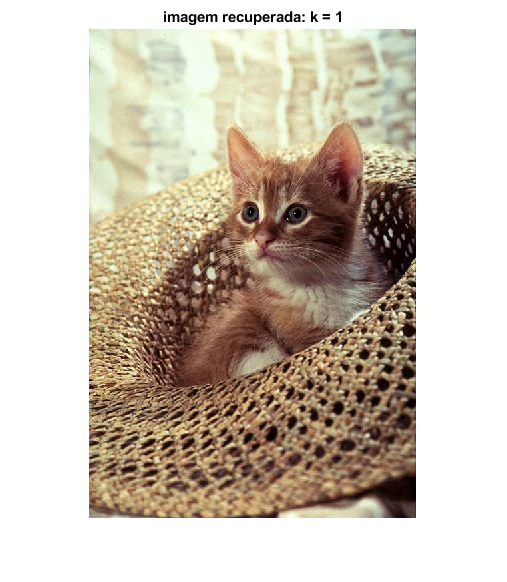

figure(4); imshow(squeeze(uint8(imagens_recuperadas(1,:,:,:)))); title('imagem recuperada: k = 1')

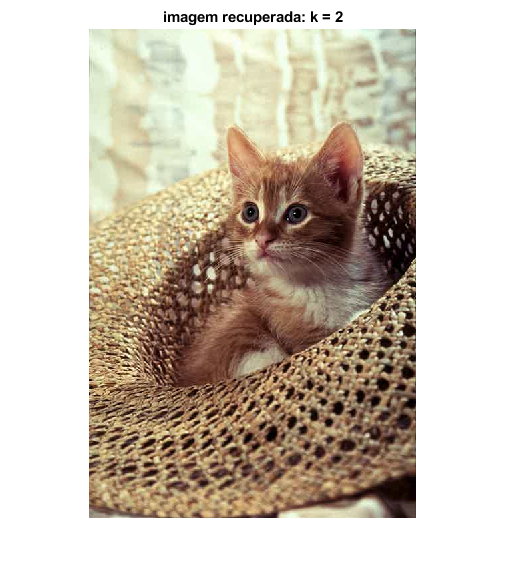

figure(5); imshow(squeeze(uint8(imagens_recuperadas(2,:,:,:)))); title('imagem recuperada: k = 2')

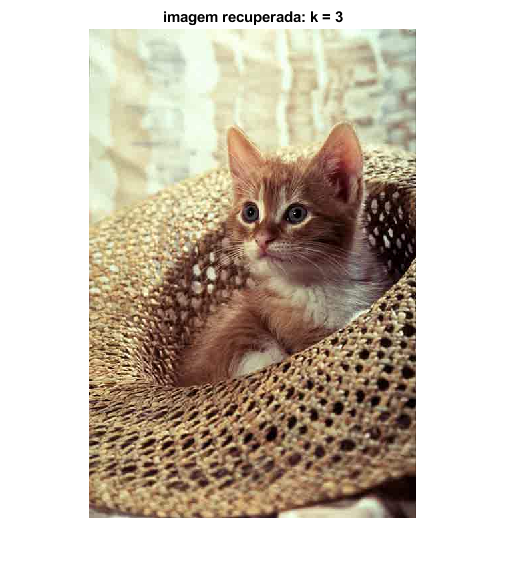

figure(6); imshow(squeeze(uint8(imagens_recuperadas(3,:,:,:)))); title('imagem recuperada: k = 3')

As PSNR's das imagens recuperadas após quantização, para $k=1,2,3$, são respectivamente 32,85 dB, 30,53 dB e 29,09 dB. É possível observar que há uma redução na qualidade da imagem quanto maior o valor de k.

Em seguida, o número de coeficientes nulos da DCT e a razão entre o número de pixels original e o número de coeficientes nulos da DCT foram calculados.

%número de coeficientes nulos da DCT
nulos_DCT = sum(sum(uint8(Y_q(1,:,:))==0)) + sum(sum(uint8(Cb_q(1,:,:))==0)) + sum(sum(uint8(Cr_q(1,:,:)==0)));

%razão entre o número de pixels original e o número de coeficientes nulos da DCT
nb_coeff = numel(Ydct) + numel(Cbdct) + numel(Crdct); 
razao = nulos_DCT/nb_coeff;


A razão encontrada foi de  92,70%. É importante ressaltar que essa razão não é a taxa de compressão da imagem.

### 5.3 Cálculo da entropia do sinal

As probabilidades de cada valor de código para os coeficientes DC e AC são calculadas abaixo:

%coef. DC: supondo no intervalo -2047:2047
k = 1;
sk_DC = -2047:2047;
p_DC = zeros(size(sk_DC));
for i = 1:length(sk_DC)
    x = sk_DC(i);
    p_DC(i) = sum(sum(Y_q(k,:,:) == x))/nb_coeff + sum(sum(Cb_q(k,:,:) == x))/nb_coeff + sum(sum(Cr_q(k,:,:) == x))/nb_coeff;
end

%coef. AC: supondo no intervalo -1023:1023
sk_AC = -1023:1023;
p_AC = zeros(size(sk_AC));
for i = 1:length(sk_AC)
    x = sk_AC(i);
    p_AC(i) = sum(sum(Y_q(k,:,:) == x))/nb_coeff + sum(sum(Cb_q(k,:,:) == x))/nb_coeff + sum(sum(Cr_q(k,:,:) == x))/nb_coeff;
end

Em seguida, a entropia $H\left(S\right)$do sinal resultante é calculada usando os valores de probabilidade obtidos.

%cálculo da entropia
H = -sum(log2(p_DC+eps).*p_DC) + -sum(log2(p_AC+eps).*p_AC)

H = 2.3429

Uma vez que o comprimento médio $\bar{L\;}$do código é limitado inferiormente pela entropia,  ou seja, $\bar{\;L} \ge H\left(S\right)$, têm-se que $\bar{\;L} \ge 2,3429\ldotp$

Considerando um comprimento médio de 3 bits por coeficiente, a imagem *cat.png, *que possui  547584 coeficientes, deve possuir tamanho de aproximadamente 205,344 KB.

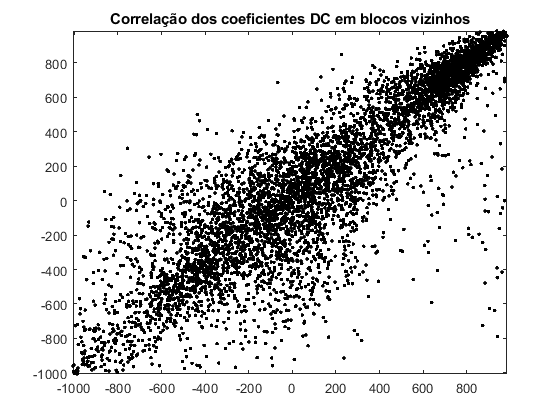

%coeficientes DC
DC_coeff = Ydct(1:8:end,1:8:end);
DC_coeff = DC_coeff(:);
figure(7); plot(DC_coeff(2:end), DC_coeff(1:end-1), '.k'); 
title('Correlação dos coeficientes DC em blocos vizinhos');
xlim([min(DC_coeff), max(DC_coeff)]); ylim([min(DC_coeff), max(DC_coeff)]);

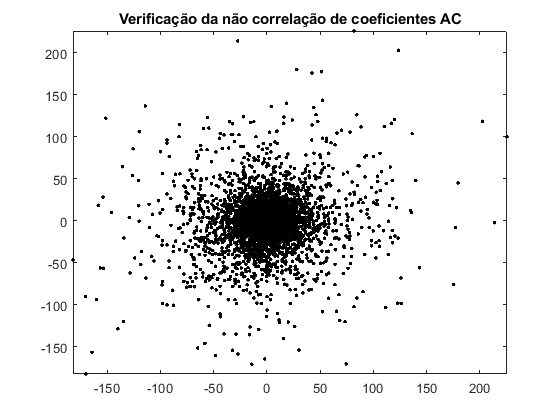

%verificar o AC para o coeficiente da linha 3 e coluna 3 de cada bloco
DC_coeff = Ydct(3:8:end,3:8:end);
DC_coeff = DC_coeff(:);
figure(8); plot(DC_coeff(2:end), DC_coeff(1:end-1), '.k'); 
title('Verificação da não correlação de coeficientes AC');
xlim([min(DC_coeff), max(DC_coeff)]); ylim([min(DC_coeff), max(DC_coeff)]);

A Figura 7 permite concluir que o coeficiente DC de um bloco é correlacionado com o coeficiente DC no bloco seguinte, uma vez que há uma dependência vista pela predominância de pontos na diagonal da Figura, ou seja, os pontos se agrupam em torno de uma reta. O mesmo não ocorreu na Figura 8, que faz a mesma verificação da Figura 7 mas com um coeficiente AC (linha 3 coluna 3 de cada bloco). A Figura 8 não apresenta nenuma correlação discernível para os coeficientes AC.  